# 测试

clc
clear
close all
addpath("src\");

n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [-2200., -8000., 100., 0., 0., 0.]';  % m, m/s
step = 1;

## 连续推力

### 间接法

tic
% [t, x] = CwIndirOpt(x0, n, tf, step, 'Riccati');
[t, x] = CwIndirOpt(x0, n, tf, step);

lambda0 = [

-1.03709925546575e-05;

-7.64011415818231e-06;

1.10740639139064e-07;

0.00233724163211481;

-0.0101864047861809;

3.64140230123426e-05];

toc

历时 2.594495 秒。


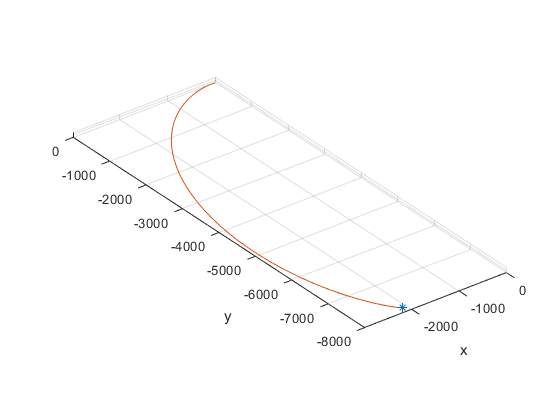

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

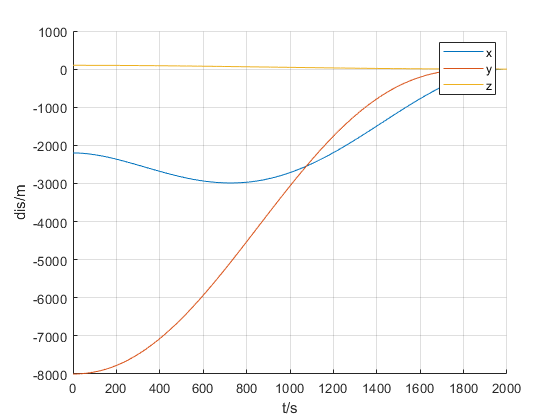

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

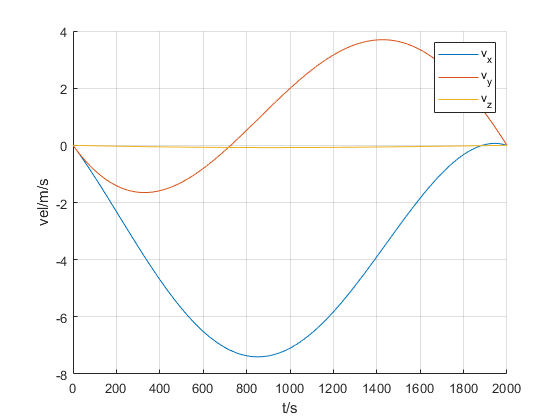

figure
hold on
plot(t, -x(:, 5))
plot(t, x(:, 4))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

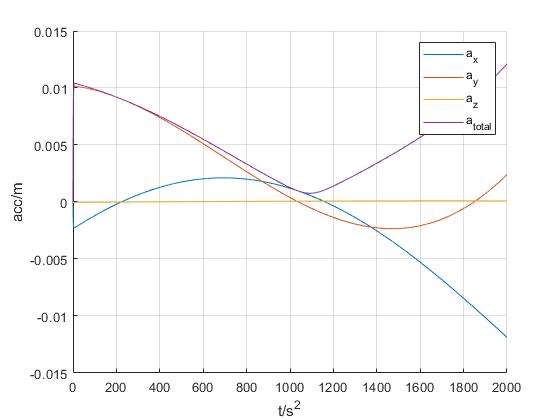

figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 11.3030

### 直接法

tic
[t, x] = CwDirOpt(x0, n, tf, step, 11);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

历时 32.355417 秒。


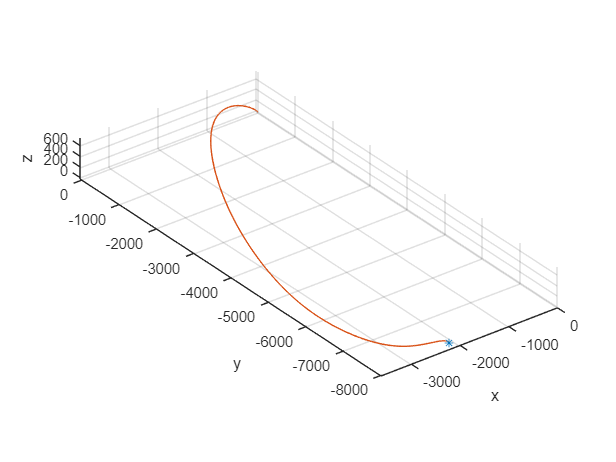

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

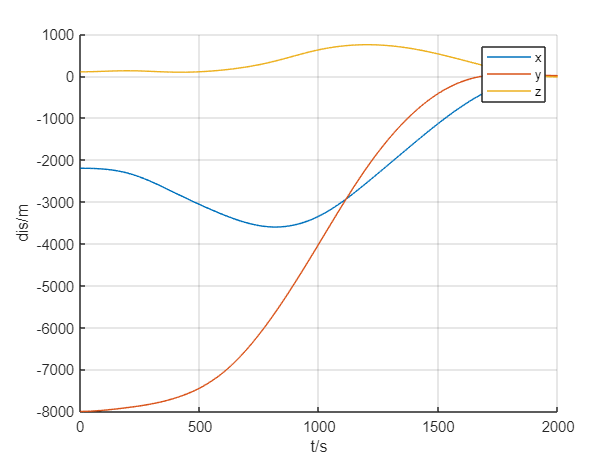

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

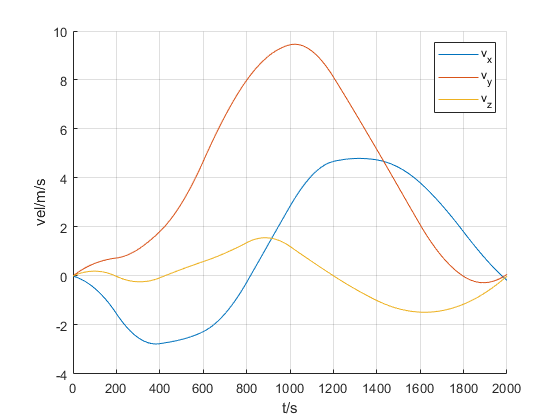

figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

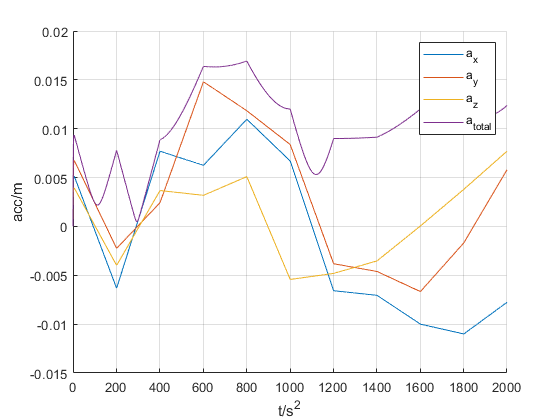

figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 20.2736

## 固定推力

x0 = [-2200., -8000., 100., 0., 0., 0.]';  % m, m/s
tf = 2000.; % s
n = 0.00111; % rad/s
tspan = 1;
f = 0.02; % m/s^2

### 间接法

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           8    3.598836e+01     1.839e+04     1.000e+00     0.000e+00     1.416e-04  
    1          16    3.598836e+01     2.462e+04     1.000e+00     2.120e+00     2.853e+07  
    2          35    3.598836e+01     2.444e+04     1.977e-02     6.483e-02     2.853e+07  
    3          49    3.598836e+01     2.267e+04     1.176e-01     4.960e-01     2.853e+07  
    4          57    1.486835e+01     1.006e+04     1.000e+00     1.055e+03     2.853e+07  
    5          65    1.946836e+01     3.188e+03     1.000e+00     2.293e+02     2.853e+07  
    6          76    1.414836e+01     2.543e+03     3.430e-01     2.655e+02     2.853e+07  
    7         104    1.414836e+01     2.543e+03     7.979e-04     4.058e-01     2.853e+07  
    8         116    2.034836e+01     1.720e+03     2.401e-01     3.102e+02     2.

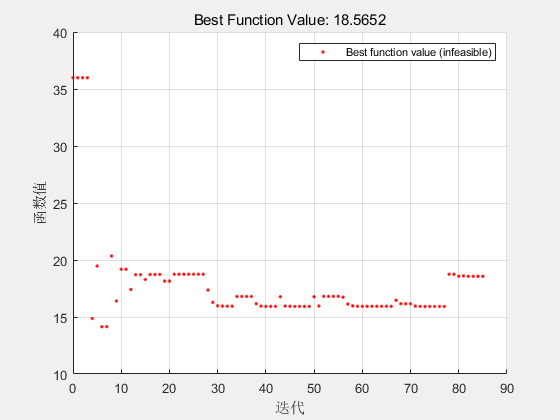


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     5.9332
   -0.1031
   -0.1047
    0.4941
   -0.0155
   -0.7943
  940.5275


fval = 18.5652

exitflag = -2

output = 包含以下字段的 struct :
         iterations: 85
          funcCount: 2993
          algorithm: 'sqp'
            message: '↵Converged to an infeasible point.↵↵fmincon stopped because the size of the current step is less than↵the value of the step size tolerance but constraints are not↵satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-09, but the relative maximum constraint↵violation, 7.069521e-03, exceeds options.ConstraintTolerance = 1.000000e-07.↵↵'
    constrviolation: 129.9916
           stepsize: 1.0929e-09
       lssteplength: 7.2575e-10
      firstorderopt: 2.8533e+07
       bestfeasible: []


tic
[t, x] = CwIndirOpt3(x0, n, f, tf, tspan);

toc

历时 48.427278 秒。


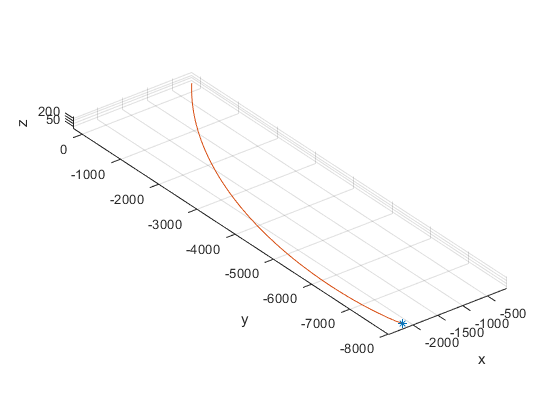


figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on

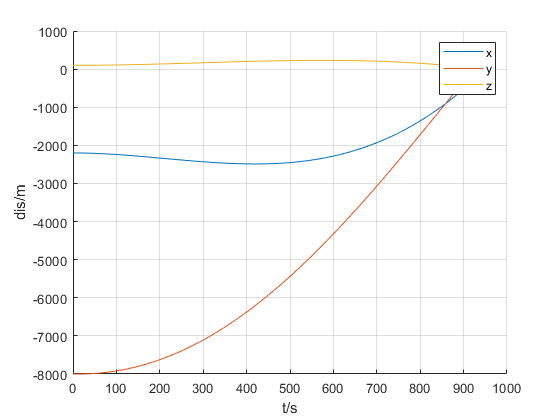

figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off

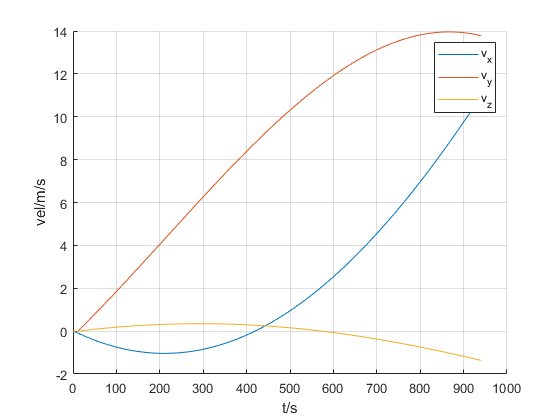

figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

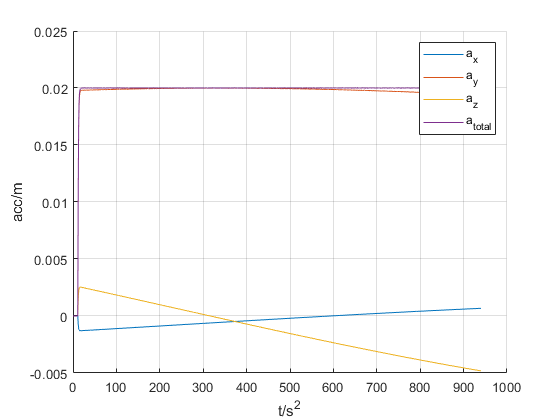

figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off

sum(a) / length(t) * tf

ans = 39.4585